clear

## Define units

global m nm kg sec J eV mass_e h_bar V_b k_1 k_2 n_e e_0 Epsi0 pi e nm1
m = 1;
kg = 1;
sec = 1;
J = 1;
pi = 3.141592;
nm = 1E-9 *(m);
nm1 = (2.40) *(nm);
eV = 1.60218E-19 *(J);
e    = 1.602176487E-19;
mass_e = 0.067*9.10938e-31 *(kg);
h_bar = (6.62607E-34)/(2*pi) *(J*sec);
V_b = 97e-3*eV;
k_1 = 0.696e-3*eV/nm;
k_2 = -0.017034e-3*eV/nm^2;
n_e = 1e15*m^(-2);
e_0 = -3.4666e-3*eV;
Epsi0 = 8.854187817620e-12*12.9;

## Determinate simulation parameters

dz = 0.25 *(nm); % Increments
zRange = 98.0 *(nm); %Z-Range of the graph
qWell_wide = 49.0 *(nm); %Size of the well

## Z-range and Potential values V

z = (-zRange/2:dz:zRange/2+dz); %Z-range to be graphed
z1 =-zRange/2:dz:-qWell_wide/2-dz;  %Z-range for the LEFT side of upper potential barrier
z2 =-qWell_wide/2:dz: qWell_wide/2;  %Z-range for Q-Well
z3 =qWell_wide/2+dz:dz:zRange/2+dz;  %Z-range for the RIGHT side of the upper potential barrier

V_upperL = e_0+k_2*((qWell_wide/2)^2)+V_b-k_1*(abs(z1)-(qWell_wide/2)); %Potential for upper barrier using LEFT Z-range
V_lower = e_0+k_2*(z2.^2); %Potential of Q-well using Z-range for Q-Well
V_upperR = e_0+k_2*((qWell_wide/2)^2)+V_b-k_1*(abs(z3)-(qWell_wide/2)); %Potential for upper barrier using RIGHT Z-range

V_1 = cat(2,V_upperL,V_lower); % Concatenates LEFT side upper potential barrier and Q-Well
V_H = cat(2,V_1,V_upperR); % Concatenates the previous array with RIGHT side upper potential barrier. This is the COMPLETE array potential values.

## Plotting the Quantum well and Constructing Hamiltonion Operator

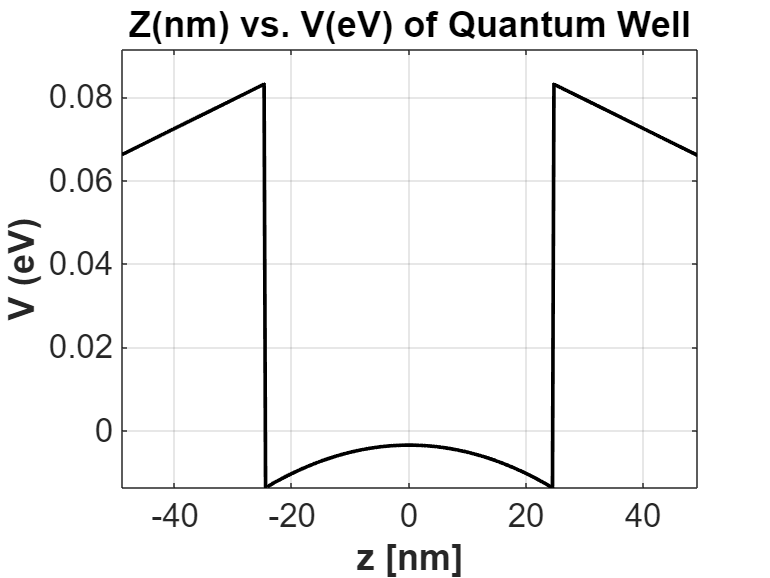

figure(1),
plot(z/nm, V_H/eV,'k'),grid on %Quantum Well plot
title('Z(nm) vs. V(eV) of Quantum Well')
xlim([min(z/nm),max(z/nm)]), ylim([min(V_H/eV),max(1.1*V_H/eV)])
xlabel('z [nm]','fontweight','bold','fontsize',16),ylabel('V (eV)','fontweight','bold','fontsize',16)


%Construct the Hamiltonian operator
% H0 = diag(h_bar^2/(mass_e*dz^2)) + V_conf);
% H1 = diag(ones(1,length(z)-1)*(-h_bar^2/(2*mass_e*dz^2)),1);
% H2 = diag(ones(1,length(z)-1)*(-h_bar^2/(2*mass_e*dz^2)),-1);
% H = H0+H1+H2

%My own hamiltonian matrix
lambda = (h_bar^2/(2*mass_e*dz^2));
n = length(V_H);
en = -1*ones(n,1);
A = spdiags([en*lambda 2*lambda+V_H.' en*lambda], -1:1, n,n);
full(A);

%Hamiltonian matrix
H  = full(A);
[fn,En] = eig(H);
E1 = En(1,1)/eV

E1 =       -0.00347487779161383


E2 = En(2,2)/eV

E2 =       0.000388099443514199


%En is a diagnal matrix of the eigenvalues
%fn is a matrix with the colomn eigenvector corresponding to the eigenvalue

## Wavefunction Plot of E_1 and E_2

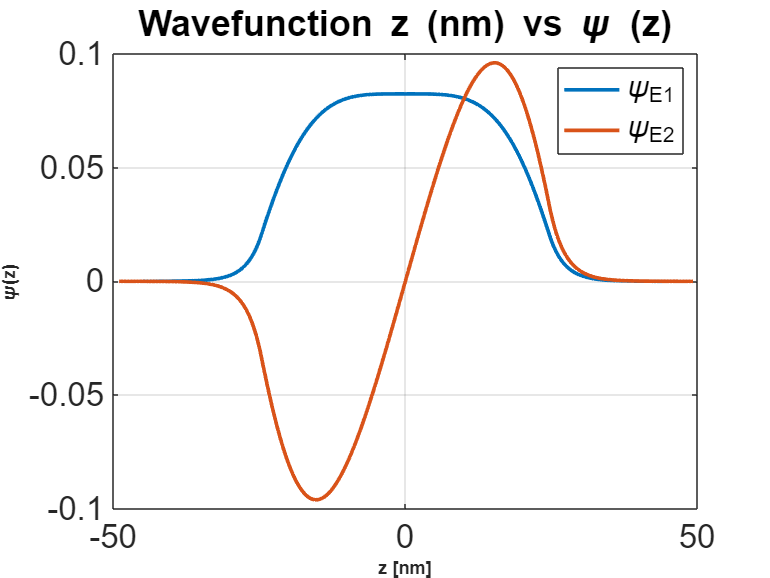

%Finding Wavefunction of E1
[d,ind] = sort(diag(En));
psi = fn(:,ind);

psi_1 = psi(:,1); %eigenfunction for E_1 (value :,1 represents the wavefunction for the first energy level)
psi_2 = psi(:,2); %eigenfunction for E_2 (value :,2 represents the wavefunction for the second energy level)

figure(2), %Wavefunction plots
plot(z/nm,psi_1);
hold on
plot(z/nm,psi_2);
hold on
grid on
title('Wavefunction z (nm) vs \psi (z)')
xlabel('z [nm]','fontweight','bold','fontsize',10)
ylabel('\psi(z)','fontweight','bold','fontsize',10)
legend('\psi_{E1}','\psi_{E2}')
hold off

%Reasures wavefunctions are valid
trapz(psi_1.^2)

ans =          0.999999999999839


trapz(psi_2.^2)

ans =          0.999999999999361


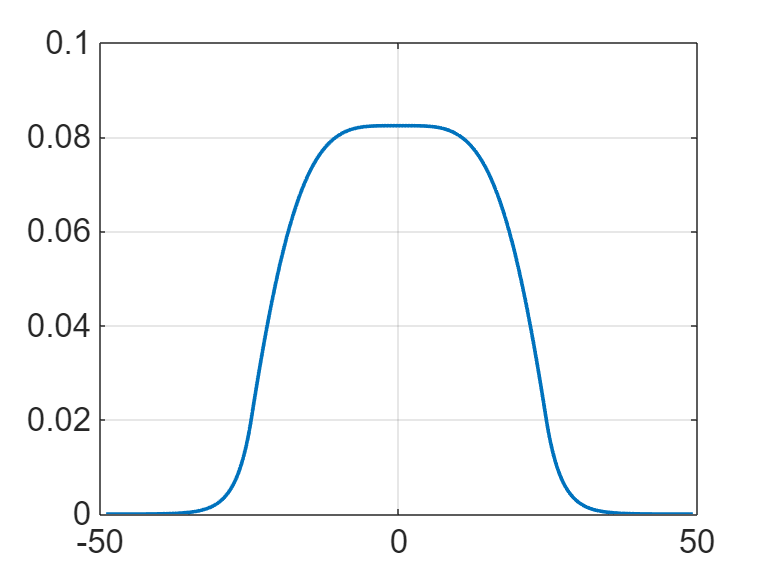


psi_1 = psi_1;
psi_2 = psi_2*nm^(-1/2);
plot(z/nm,psi_1);

## Solving for VH + V_XC

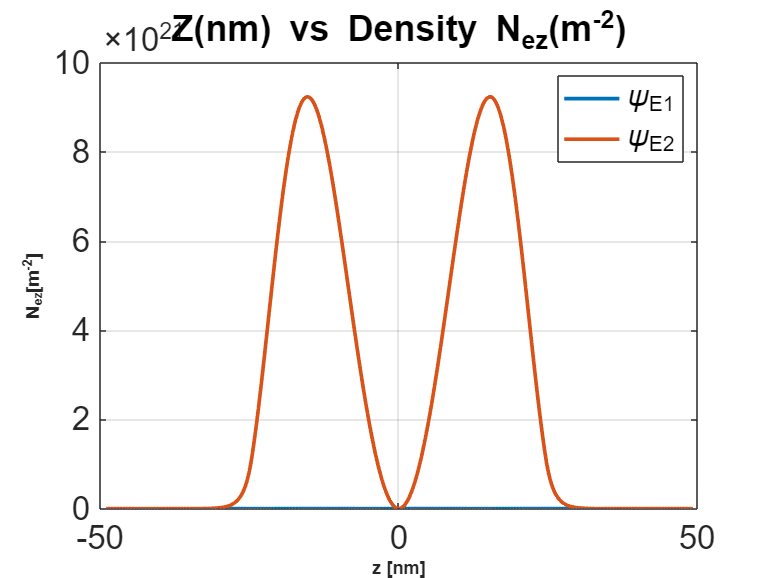

%Solving for N_ez, V_xc, and V2 for \phi_1
N_ez = n_e*((abs(psi_1).^2));
V_xc = -0.611*((e^2)/(4*pi*Epsi0))*((3*(N_ez))/(4*pi)).^(1/3);
V_sc = V_H + (V_xc.');

%Solving for N_ez, V_xc, and V2 for \phi_2
N_ez_2 = n_e*(psi_2.^2);
V_xc_2 = -0.611*((e^2)/(4*pi*Epsi0))*((3*(N_ez_2))/(4.*pi)).^(1/3);
V_sc_2 = V_H + (V_xc_2.');

figure(3),
plot(z/nm, N_ez);
hold on
plot(z/nm, N_ez_2);
grid on
title('Z(nm) vs Density N_{ez}(m^{-2})')
xlabel('z [nm]','fontweight','bold','fontsize',10)
ylabel('N_{ez}[m^{-2}]','fontweight','bold','fontsize',10)
legend('\psi_{E1}','\psi_{E2}')
hold off

figure(4),
grid on

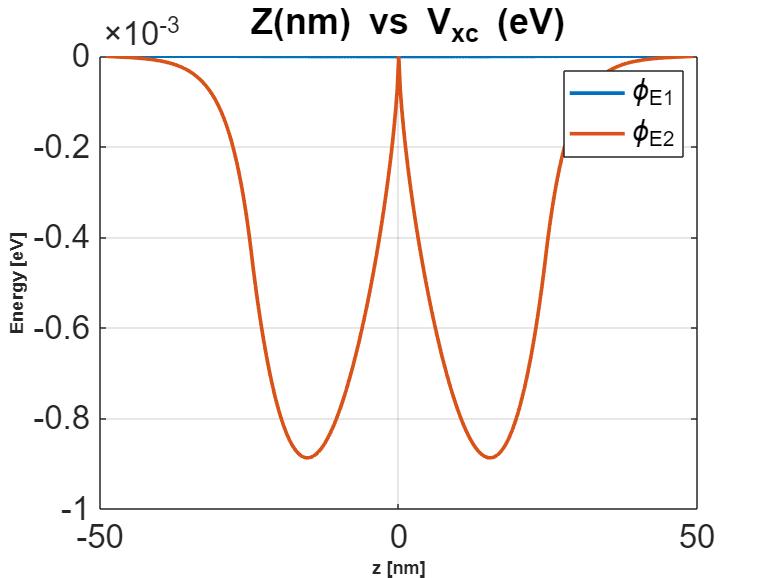

plot(z/nm, V_xc/eV);
hold on
plot(z/nm, V_xc_2/eV);
title(' Z(nm) vs V_{xc} (eV)')
xlabel('z [nm]','fontweight','bold','fontsize',10)
ylabel('Energy [eV]','fontweight','bold','fontsize',10)
legend('\phi_{E1}','\phi_{E2}')
hold off

## Solving for Psi again 203 more times

Using \psi_{E1}

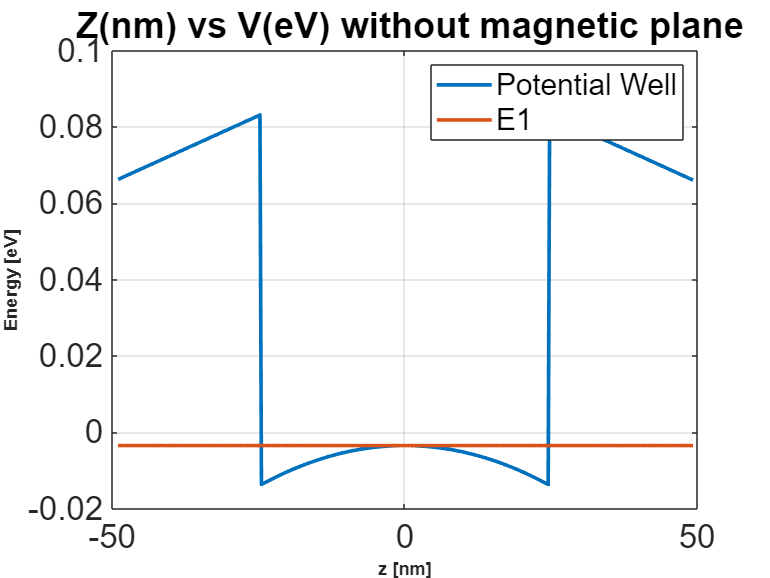

V_2 = V_H;
n = 0;
while n ~= 5
    %Construct the Hamiltonian operator using V2
    H0_2 = diag((h_bar^2/(mass_e*dz^2)) + V_2);
    H1_2 = diag(ones(1,length(z)-1)*(-h_bar^2/(2*mass_e*dz^2)),1);
    H2_2 = diag(ones(1,length(z)-1)*(-h_bar^2/(2*mass_e*dz^2)),-1);
    H_2 = H0_2+H1_2+H2_2;
    %Solves Eigenvectors and values
    [fn2,En2] = eig(H_2);
    %Second Wavefunction
    psi_1_2 = fn2(:,1);
    %Solving for N_ez, V_xc, and V2
    N_ez_3 = n_e*(psi_1_2.^2);
    V_xc_3 = -0.611*((e.^2)/(4*pi*Epsi0))*((3*(N_ez_3))/(4.*pi)).^(1/3);
    V3 = V_2 + (V_xc_3.');
    V_2 = V3;
    n = n + 1;
end
N_ez_3;

E1 = En2(1,1)/eV;
E2 = En2(2,2)/eV;
E1 = E1*ones(length(z),1);
plot(z/nm, V3/eV)
hold on
plot(z/nm, E1)
hold off 
title(' Z(nm) vs V(eV) without magnetic plane')
grid on
xlabel('z [nm]','fontweight','bold','fontsize',10)
ylabel('Energy [eV]','fontweight','bold','fontsize',10)
legend('Potential Well','E1')
hold off

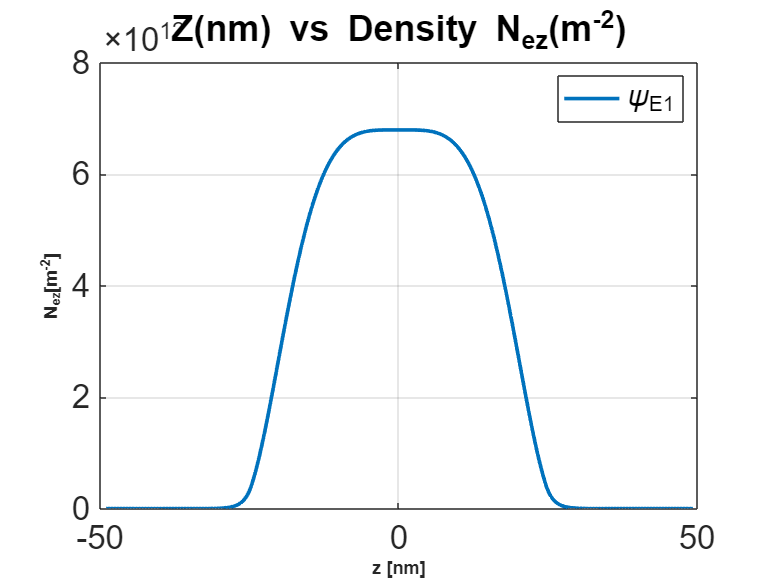

plot(z/nm, N_ez_3);
grid on
title('Z(nm) vs Density N_{ez}(m^{-2})')
xlabel('z [nm]','fontweight','bold','fontsize',10)
ylabel('N_{ez}[m^{-2}]','fontweight','bold','fontsize',10)
legend('\psi_{E1}')
hold off

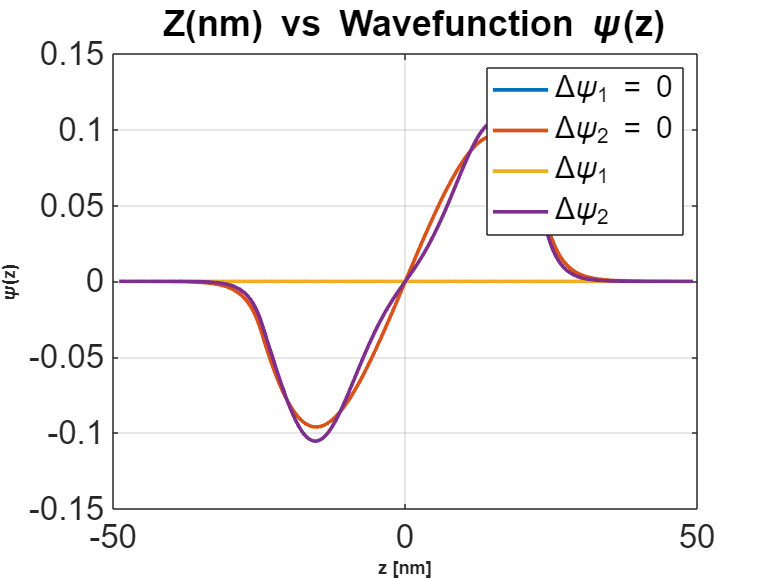


% Using \psi_{E2}
V_2_2 = V_sc_2;
j = 0;
while j ~= 50
    %Construct the Hamiltonian operator using V2
    H0_2 = diag((h_bar^2/(mass_e*dz^2)) + V_2_2);
    H1_2 = diag(ones(1,length(z)-1)*(-h_bar^2/(2*mass_e*dz^2)),1);
    H2_2 = diag(ones(1,length(z)-1)*(-h_bar^2/(2*mass_e*dz^2)),-1);
    H_2 = H0_2+H1_2+H2_2;
    %Solves Eigenvectors and values
    [fn2,En2] = eig(H_2);
    %Second Wavefunction
    psi_2_2 = fn2(:,2)*nm^(-1/2);
    %Solving for N_ez, V_xc, and V2
    N_ez_3 = n_e*(psi_2_2.^2);
    V_xc_3 = -0.611*((e.^2)/(4*pi*Epsi0))*((3*(N_ez_3))/(4.*pi)).^(1/3);
    V3_2 = V_2_2 + (V_xc_3.');
    V_2_2 = V3_2;
    j = j + 1;
end

%Wavefunction comparison
figure(5),
plot (z/nm, psi_1*nm^(1/2))
hold on
plot(z/nm, psi_2*nm^(1/2))
hold on
plot(z/nm, psi_1_2*nm^(1/2))
hold on
plot(z/nm, psi_2_2*nm^(1/2))
title(' Z(nm) vs Wavefunction \psi(z)')
grid on
xlabel('z [nm]','fontweight','bold','fontsize',10)
ylabel('\psi(z)','fontweight','bold','fontsize',10)
legend('\Delta\psi_{1} = 0','\Delta\psi_{2} = 0','\Delta\psi_{1}','\Delta\psi_{2}')
hold off


%Energy comparison
figure(6),
plot (z/nm,V_H/eV)

title(' Z(nm) vs V(eV) without magnetic plane')
grid on
xlabel('z [nm]','fontweight','bold','fontsize',10)
ylabel('Energy [eV]','fontweight','bold','fontsize',10)
legend('\Delta E = 0','\Delta E_{2}')

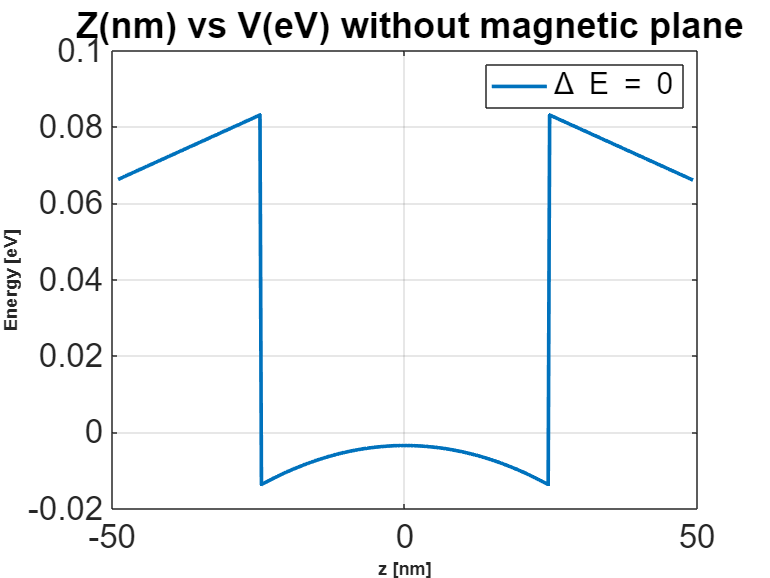

hold off

## Calculation of New E when Adding in-pane Magnetic field; (K_x) = 0

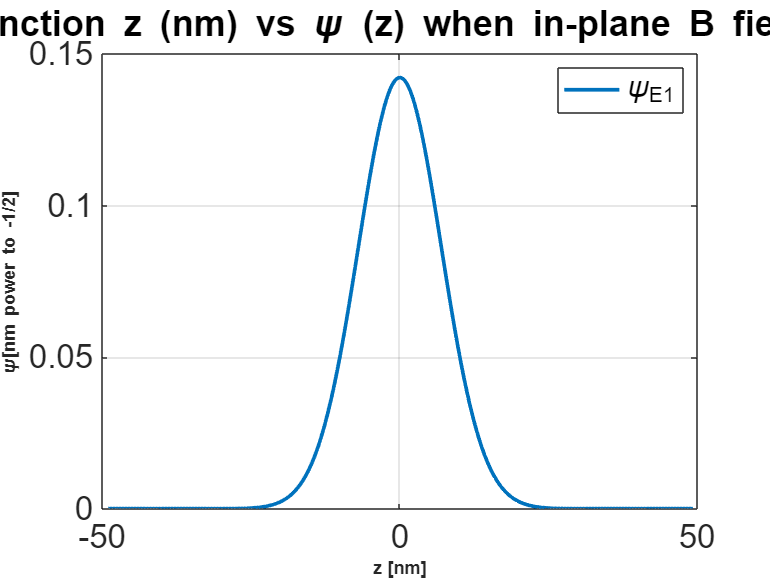

k_x = 0:0.4*10^(-10):10^(-11);
A = zeros(1,15);
B = zeros(1,15);
F = zeros(1,15);
n = 0;
for n = 1:15
B_y = n-1+0.0000000000000000000001;
omega = abs(e)*(B_y)/mass_e;
E_m = ((mass_e)*(omega)^2)*(z).^2/2 ;
V_tot = V_2+ E_m; %New energy!

H0_3 = diag((h_bar^2/(mass_e*dz^2)) + V_tot);
H1_3 = diag(ones(1,length(z)-1)*(-h_bar^2/(2*mass_e*dz^2)),1);
H2_3 = diag(ones(1,length(z)-1)*(-h_bar^2/(2*mass_e*dz^2)),-1);
H_3 = H0_3+H1_3+H2_3;
[fn3,En3] = eig(H_3);

%Finding Wavefunction of new E1
[d2,ind2] = sort(diag(En3));
psi_b = fn3(:,ind);
a = En3(1,1)/eV;
f = En3(2,2)/eV;

A(n) = a;
B(n) = B_y;
F(n) = f;
end
psi_1_b = -1*psi_b(:,1);
plot(z/nm,psi_1_b);
grid on
title('Wavefunction z (nm) vs \psi (z) when in-plane B field aplied')
xlabel('z [nm]','fontweight','bold','fontsize',10)
ylabel('\psi[nm power to -1/2]','fontweight','bold','fontsize',10)
legend('\psi_{E1}')
hold off

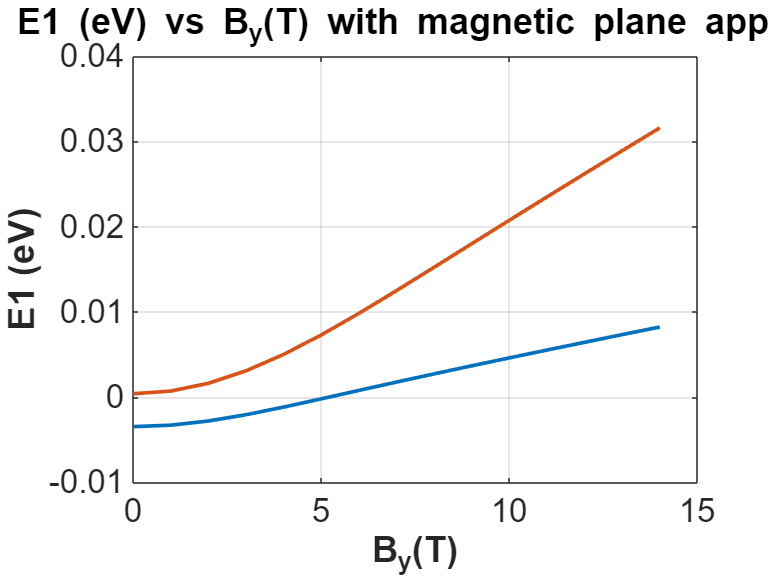

plot (B,A)
hold on
plot (B,F)
title(' E1 (eV) vs B_y(T) with magnetic plane applied')
grid on
xlabel('B_y(T)','fontweight','bold','fontsize',10)
ylabel('E1 (eV)','fontweight','bold','fontsize',10)
hold off

### **Energy Spectrum when in-plane Magnetic Field is not 0**

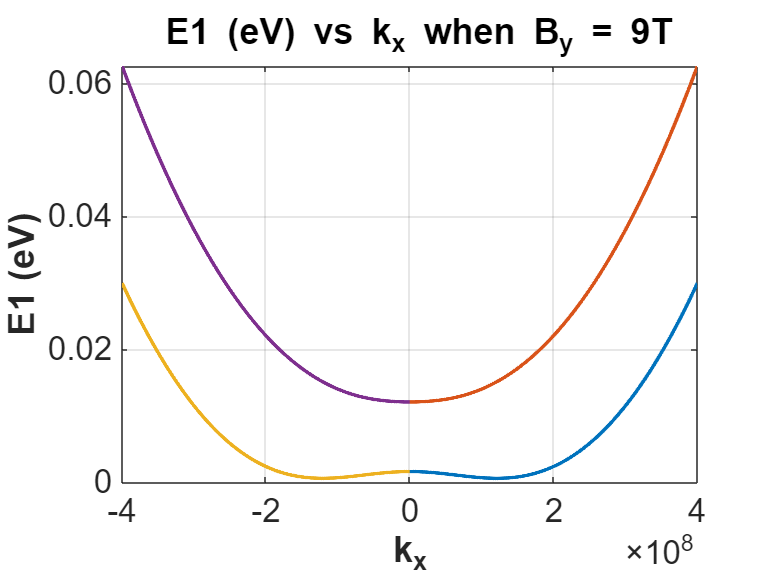

k_x = (0:0.0004/nm :0.4/nm)';
B_y = 6.848;
omega = abs(e)*(B_y)/mass_e;
z_0 = (h_bar*k_x)/(mass_e*omega);
C = zeros(1,1001);
D = zeros(1,1001);
for n = 1:length(C)
E_n = ((mass_e)*(omega)^2)*(z-(z_0(n)*ones(1,length(z)))).^2/2;
V_tot = V_2+ E_n; %New energy!
H0_3 = diag((h_bar^2/(mass_e*dz^2)) + V_tot);
H1_3 = diag(ones(1,length(z)-1)*(-h_bar^2/(2*mass_e*dz^2)),1);
H2_3 = diag(ones(1,length(z)-1)*(-h_bar^2/(2*mass_e*dz^2)),-1);
H_3 = H0_3+H1_3+H2_3;
[fn3,En3] = eig(H_3);
%Finding Wavefunction of new E1
[d2,ind2] = sort(diag(En3));
psi_b = fn3(:,ind);
c = En3(1,1)/eV;
d = En3(2,2)/eV;
C(n) = c;
D(n) = d;
end
plot(k_x, C, k_x, D, -k_x, C, -k_x, D)
title(' E1 (eV) vs k_x when B_y = 9T')
grid on
xlabel('k_x','fontweight','bold','fontsize',10)
ylabel('E1 (eV)','fontweight','bold','fontsize',10)
hold off

### ***Energy Spectrum when In-Plane Field is Zero***

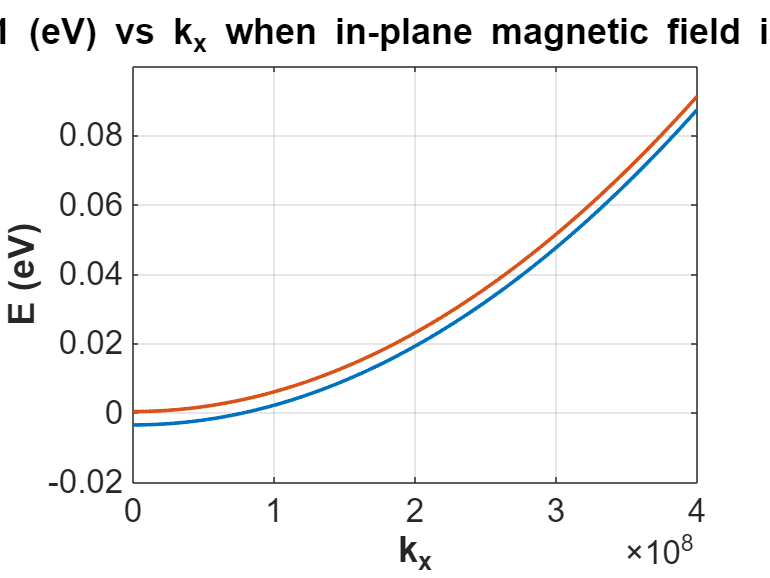

k_x = (0:0.001017/nm :0.4/nm)';
B_y = 0;
G1 = zeros(1,394);
G2 = G1;
Vconf = zeros(1,394);

n = 1;

for n = 1:length(k_x)
E_n0 = (h_bar*k_x(n)).^2/(2*mass_e);
V_tot0 = V_2+ E_n0; %New energy!
H0_30 = diag((h_bar^2/(mass_e*dz^2)) + V_tot0);
H1_30 = diag(ones(1,length(z)-1)*(-h_bar^2/(2*mass_e*dz^2)),1);
H2_30 = diag(ones(1,length(z)-1)*(-h_bar^2/(2*mass_e*dz^2)),-1);
H_30 = H0_30+H1_30+H2_30;
[fn30,En30] = eig(H_30);
%Finding Wavefunction of new E1
[d20,ind20] = sort(diag(En30));
psi_b0 = fn30(:,ind);
G1(n) = En30(1,1)/eV;
G2(n) = En30(2,2)/eV;

end

k_x = (0:0.001017/nm :0.4/nm)';
plot(k_x,G1);
hold on
plot(k_x,G2);
title(' E1 (eV) vs k_x when in-plane magnetic field is zero')
grid on
xlabel('k_x','fontweight','bold','fontsize',10)
ylabel('E (eV)','fontweight','bold','fontsize',10)

hold off

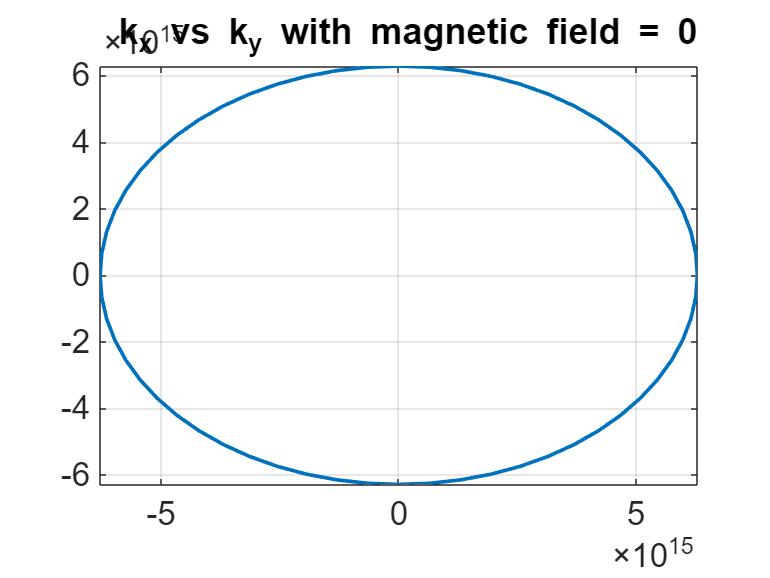


k_x1 = (0:0.00003965/nm :0.0793/nm)';
k_f = 2*pi*n_e;
theta0 = 0:pi/30:2*pi;
x = k_f.*cos(theta0);
y = k_f.*sin(theta0);
plot(x,y);
title(' k_x vs k_y with magnetic field = 0')
grid on
hold off

## **Cycltron effective mass when B_y = 0**

k_f = sqrt(k_f);

### ***When m_y/ m_x = 4***

R = (k_f);
theta = linspace(0, 2*pi, 394); 
kx = R * cos(theta);
ky = sqrt(4*k_f^2 - 4*kx.^2);
E = @(k,m_x,m_y) ((h_bar^2/2) * (k(1)^2/m_x + k(2)^2/m_y))

E = function_handle with value:
    @(k,m_x,m_y)((h_bar^2/2)*(k(1)^2/m_x+k(2)^2/m_y))


gradE = @(k,m_x,m_y) [h_bar^2 * k(1) /m_x, h_bar^2 * k(2) /m_y]

gradE = function_handle with value:
    @(k,m_x,m_y)[h_bar^2*k(1)/m_x,h_bar^2*k(2)/m_y]


integral_value = 0;
m_x = 1; 
m_y = 4;
for i = 1:length(theta)
    k = [kx(i), ky(i)];    
    grad_E = gradE(k,m_x,m_y);     
    grad_E_magnitude = sqrt(grad_E(1)^2 + grad_E(2)^2); 
     if i < length(theta)
        dk = sqrt((kx(i+1) - kx(i))^2 + (ky(i+1) - ky(i))^2);
    else
        dk = sqrt((kx(1) - kx(i))^2 + (ky(1) - ky(i))^2); 
     end
         integral_value = integral_value + (dk / grad_E_magnitude);
end
integral_value = (h_bar^2 / (2*pi)) * integral_value;
disp(integral_value)

    1.9949



***When m_y/ m_x = 1***

theta2 = linspace(0, 2*pi, 394); 
kx2 = 2*R * cos(theta2);
ky2 = 2*R * sin(theta2);
integral_value = 0;
m_x = 1; 
m_y = 1;
for i = 1:length(theta2)
    k2 = [kx2(i), ky2(i)];    
    grad_E = gradE(k2,m_x,m_y);     
    grad_E_magnitude = sqrt(grad_E(1)^2 + grad_E(2)^2); 
     if i < length(theta)
        dk = sqrt((kx2(i+1) - kx2(i))^2 + (ky2(i+1) - ky2(i))^2);
    else
        dk = sqrt((kx2(1) - kx2(i))^2 + (ky2(1) - ky2(i))^2); 
     end
         integral_value = integral_value + (dk / grad_E_magnitude);
end
integral_value = (h_bar^2 / (2*pi)) * integral_value;
disp(integral_value)

    1.0000



## **Fermi Enegy when B_y = 0**

### **Theoretical Method**

K_B = 8.617*10^(-5); % Boltzmann Constant in eV/K
DOS = mass_e/(pi*h_bar^2); % Density of states 
Fermi_J = (n_e)/DOS;% Fermi energy in J
Fermi_eV = (Fermi_J)/e; % Fermi energy in eV
Temp = Fermi_eV/K_B % The corresponding temperature

Temp = 41.4641

**Numerical Method 2**

% Numerical settings
k_max = 1e10; % Maximum wavevector to consider (m^-1)
num_points = 10000; % Number of discretized points in k-space

% Discretize k-space
k = linspace(0, k_max, num_points);
dk = k(2) - k(1);

% Define the DOS function g(k)
g = @(k) (4 * pi * k) / (4 * pi^2);

% Initialize cumulative sum for n_e
n_states = 0; % Number of states
k_F = 0; % Initialize Fermi wavevector

% Loop over the k values to find k_F
for i = 1:length(k)
    n_states = n_states + g(k(i)) * dk; % Increment total number of states
    
    % Stop when the number of states exceeds the target electron density
    if n_states >= n_e
        k_F = k(i); % Save the Fermi wavevector
         disp('Condition met. Breaking the loop.');
        break;
    end
end

Condition met. Breaking the loop.


% Calculate Fermi Energy
EF = (h_bar^2 * k_F^2) / (2 * mass_e);
Ef = EF/e

Ef = 0.0035

Temp0 = Ef/K_B

Temp0 = 41.1940

## **Fermi Enegy when B_y = ? T **

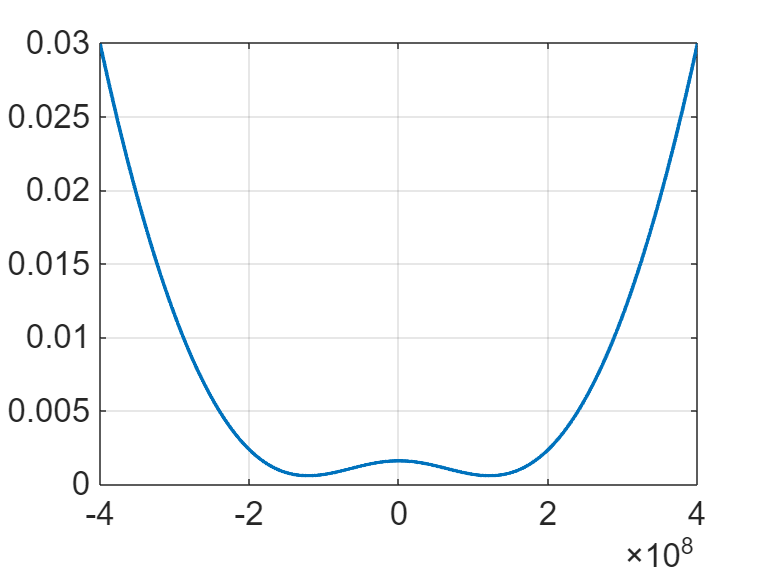

C0 = C;
C1 = flip(C);
F = [C1,C0];
kx = linspace(-0.4/nm,0.4/nm,2002);
plot(kx,F)

ky = linspace(-0.4/nm,0.4/nm,2002);
[Ex,ky]=meshgrid(F,ky);
E_tot = Ex + (h_bar * ky).^2/(2*mass_e*eV);

ky = linspace(-0.4/nm,0.4/nm,2002);
[kx,ky]=meshgrid(kx,ky);
%surf(kx, ky, E_tot);
%colormap(jet);     
%colorbar; 
%xlabel('kx-axis');
%ylabel('ky-axis');
%zlabel('E-axis');
%title('E vs k when B_y = 9T ');
E_flat = unique(sort(round(E_tot(:), 3,"significant")));
dk = 0.0004/nm;
E_F = 0;
 
for i = 1:length(E_flat)
    E_F_trial = E_flat(i); % Current trial Fermi energy
    n_states = 0;% Initialize the electron density counter
    for j = 1:length(kx)
        if E_F_trial > F(j) % Check if E_F > E(k_x)
            % Add contribution to n_states
            n_states = n_states + (sqrt((2 * mass_e / h_bar^2)*(E_F_trial - F(j))*eV)*dk)/(pi^2);
        end
    end

    if abs(n_states - n_e) <= 0.01*n_e
        E_F = E_F_trial; % Save the Fermi energy
        disp('Condition met. Breaking the loop.');
        display(E_F);
        break; % Exit the loop
    end
end

Condition met. Breaking the loop.


E_F = 0.0016

E_f9 = E_F;
Temp9 = E_f9/K_B

Temp9 = 18.1037

## **Cylctron Effective Mass when B_y = ? T at Fermi Energy**

% Check file:'EffectiveMass_At_FermiEnergy'

## Plot Mass vs. Energy at B_y = ?T

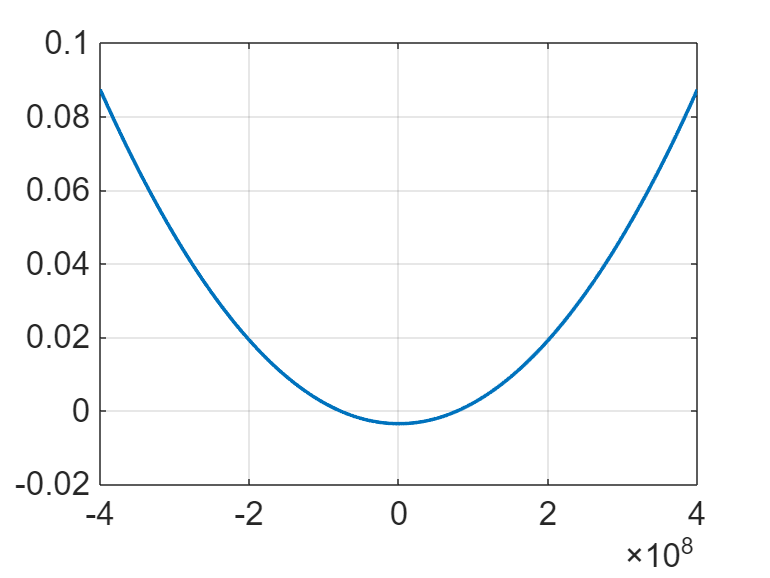

% Check file:'EffectiveMass_Vs_Energy'
E_0 = [flip(G1),G1];
kx = linspace(-0.4/nm,0.4/nm,788);
plot(kx,E_0)

min(E_0)

ans = -0.0035

toc
disp('Done.')